airfoils = { ...
    'NACA 2312', NACA(0.02, 0.3, 0.12); ...
    'NACA 2324', NACA(0.02, 0.3, 0.24); ...
    'NACA 4412', NACA(0.04, 0.4, 0.12); ...
    'NACA 4424', NACA(0.04, 0.4, 0.24); ...
    };

tat = thin_airfoil_theory()

tat =   thin_airfoil_theory with no properties.


C_l = tat.calculate_cl(airfoils{1,2}, deg2rad(5))

C_l = NaN

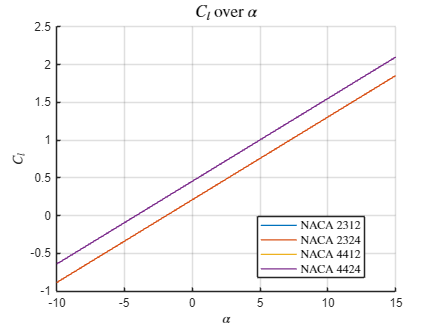



figure('Name','NACA 4-Digit Airfoils','NumberTitle','off');
hold on; grid on;
colors = lines(size(airfoilDefs,1)); 

aoa = -10:.5:15;
cl_arr = zeros(size(aoa,1), size(airfoilDefs,1));
for j = 1:size(airfoilDefs,1)
    for i = 1:size(aoa,2)
        cl_arr(i,j) = tat.calculate_cl_numeric(deg2rad(aoa(i)), ...
            airfoils{j,2}.m, airfoils{j,2}.p, 1);
    end

    plot(aoa, cl_arr(:,j), 'Color', colors(j,:), 'LineWidth', 1.2, ...
        'DisplayName',[airfoils{j,1}]);
end

title('$C_l$ over $\alpha$', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('$\alpha$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('$C_l$', 'Interpreter', 'latex', 'FontSize', 12);
legend('Location','best', 'Interpreter', 'latex', 'FontSize', 10);
hold off;